% fileID = fopen('matt-vdata.bin', 'r');
% raw_data = fread(fileID, 'int8');
fileID = fopen('gioveAandB_short.bin', 'r');
raw_data = fread(fileID, 'int8');

## Straightforward method - using time mulitplication

fc = 3e6;
fs = 26e6;
fca = 1.023e6;
ts = 1/fs;
ms  = 2;
Len = ms*fs/1000;
nn = [0:Len-1];
ca_freq = 1023000;
pros_data = raw_data(1:Len)';

numSatalites = 32;
satArray = zeros(1,numSatalites);

tic
for svnum = 1:numSatalites
    code = digitizg(Len/2,fs,0,svnum);
    search_arr = 1:5:fs/1000;
    yy = zeros(length(search_arr),Len/4);
    j = 1;
    for CAstart = search_arr
        prod = pros_data(CAstart:CAstart+Len/2 - 1).*code;
        prodFFT = abs(fftshift(fft(prod)));
        yy(j,:) = prodFFT(Len/4+1:end);   
        j = j + 1;
    end
    M = max(yy,[],'all');
    [dopIndex, startShift] = find(yy == M);
    satArray(svnum) = M;
end
toc

Elapsed time is 186.192206 seconds.


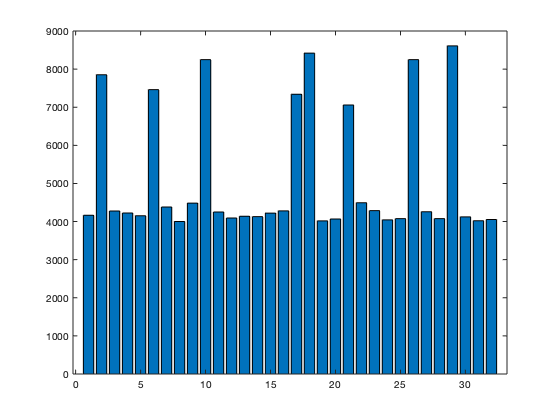

bar(satArray)

## Using 1ms and circular multiplication

fc = 3e6;
fs = 26e6;
fo = 12.5e6;
fca = 1.023e6;
ts = 1/fs;
ms  = 1;
Len = ms*fs/1000;
nn = [0:Len-1];
ca_freq = 1023000;
pros_data = raw_data(1:Len)';

numSatalites = 32;
satArray = zeros(1,numSatalites);

tic
for svnum = 1:numSatalites
    code = digitizg(Len,fs,0,svnum);
    search_arr = 1:10:fs/1000;
    yy = zeros(length(search_arr),Len/2);
    j = 1;
    for shift = search_arr
        prod = pros_data.*circshift(code, shift);
        prodFFT = abs(fftshift(fft(prod)));
        yy(j,:) = prodFFT(Len/2+1:end);   
        j = j + 1;
    end
    M = max(yy,[],'all');
    [dopIndex, startShift] = find(yy == M);
    satArray(svnum) = M;
end
toc

Elapsed time is 87.306080 seconds.


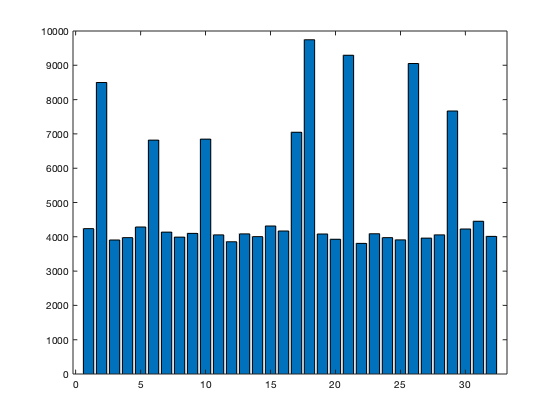

bar(satArray)

## FFT Algo

% fc = 3.045e6;
% fs = 26e6;
% ts = 1/fs;

fc = 4130400;
fs = 16367600;
freq_vector= 2*pi*[(fc - 10e3):1e3:(fc+10e3)];
ts = 1/fs;

ms  = 1;
Len = ceil(ms*fs/1000);
% Len = ms*fs/1000;
nn = [0:Len-1];
ca_freq = 1023000;
% dataStart = 2*Len;
pros_data = raw_data(1:Len)';

% These indices to help fix frequency range over which we search
fcInd = (Len)*fc/(fs)+1;
deltaInd10K = (Len)*0.01e6/(fs);
deltaInd1K = (Len)*1e3/(fs);

numSatalites = 32;
satArray = zeros(numSatalites,3);
n = Len;
tic
data = fft(pros_data);
for svnum = 1:numSatalites
%     Setting search array in freq domain
    freqSearchArr = (fcInd - deltaInd10K):deltaInd1K:(fcInd + deltaInd10K);
    
    yy = zeros(length(freqSearchArr),Len);
    
    j = 1;
    code = digitizg(Len,fs,0,svnum);
    for k = freqSearchArr
        ca_fft = conj(fft(code.*exp(1i*2*pi*k.*nn/Len)));
        
        yy(j,:) = abs(ifft(data.*ca_fft));
        j = j + 1;
    end
    M = max(yy,[],'all');
    satArray(svnum,1) = M;
    [dopIndex, startShift] = find(yy == M);
    coarse_index = freqSearchArr(dopIndex);
    f_coarse = (coarse_index - 1)*fs/Len;
    
%     get 5s of data
    pros_data5ms = raw_data(startShift:startShift + 2*Len - 1)';
    cw_5ms = pros_data5ms .* [code code];
    
    % ***** find medium freq resolution 400Hz apart *****
    for i = [1:3]
        fr = f_coarse - 400 + (i-1)*400;
        med_frq(i) = abs(sum(cw_5ms(1:Len) .* exp(j*2*pi*fr*ts*nn))); 
    end
    [med_amp, med_rw] = max(med_frq); % find highest peak 
    f_med = f_coarse + 200*(med_rw-2);
    fr = f_med;
    
    % ***** find fine freq *****
    zb5 = cw_5ms .* exp(1i*2*pi*fr*ts*[0:2*Len - 1]); % one DFT component 
    zc5 = diff(-angle(sum(reshape(zb5,n,2)))); % find difference angle 
    zc5 = zc5/(2*pi);
    zc5fix = zc5;
    
    % ***** Adjust phase and take out possible phase shift *****
    threshold = 0.23; 
    for i = 1
        if abs(zc5(i))>threshold% for angle adjustment 
            zc5(i) = zc5fix(i)-1;
            if abs(zc5(i))>threshold
                zc5(i) = zc5fix(i)+1; % end
                if abs(zc5(i))>0.22 % for pi phase shift correction
                    zc5(i) = zc5fix(i)-0.5;
                    if abs(zc5(i))>threshold
                        zc5(i) = zc5fix(i) - 1.5;
                        if abs(zc5(i))>threshold
                            zc5(i) = zc5fix(i)+0.5;
                        end
                    end
                end
            end
        end
    end
    
    dfrq = mean(zc5)*1000;
    frr = fr+dfrq;% fine freq
    satArray(svnum,2) = frr;
    satArray(svnum,3) = startShift;
    
end
toc

Elapsed time is 3.180511 seconds.


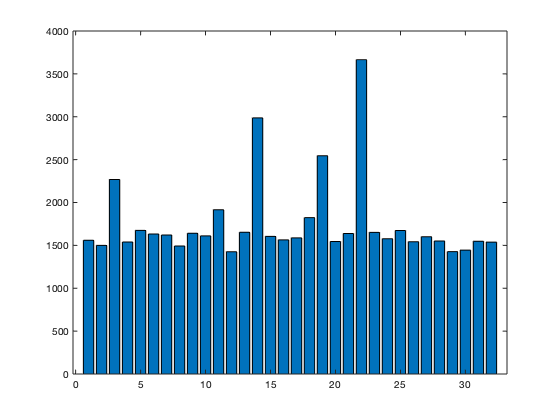

bar(satArray(:,1))

numSatalites = 32;
satArray = zeros(numSatalites,3);
n = Len;
tic
data = fft(pros_data);
for svnum = 1:numSatalites
%     Setting search array in freq domain
    freqSearchArr = (fcInd - deltaInd10K):deltaInd1K:(fcInd + deltaInd10K);
    
    yy = zeros(length(freqSearchArr),Len);
    
    j = 1;
    code = digitizg(Len,fs,0,svnum);
    for k = freqSearchArr
        ca_fft = conj(fft(code.*exp(1i*2*pi*k.*nn/Len)));
        
        yy(j,:) = abs(ifft(data.*ca_fft));
        j = j + 1;
    end
    M = max(yy,[],'all');
    satArray(svnum,1) = M;
    [dopIndex, startShift] = find(yy == M);
    coarse_index = freqSearchArr(dopIndex);
    f_coarse = (coarse_index - 1)*fs/Len;
    
%     get 10s of data
    pros_data10ms = raw_data(startShift:startShift + 10*Len - 1)';
    longCAcode = [code code code code code code code code code code];
    cw_10ms = pros_data10ms .* longCAcode;
    
    fftNumPts = 8*(2^(nextpow2(length(cw_10ms))));
    
    fftxc = abs(fft(cw_10ms, fftNumPts)); 
        
    uniqFftPts = ceil((fftNumPts + 1) / 2);
    [fftMax, fftMaxIndex] = max(fftxc(5 : uniqFftPts-5));
    
    fftFreqBins = (0 : uniqFftPts-1) * fs/fftNumPts;
    
    satArray(svnum,2) = fftFreqBins(fftMaxIndex);
    satArray(svnum,3) = startShift;
    
end
toc

Elapsed time is 5.778132 seconds.


bar(satArray(:,1))